# Template of Manipulator Short project: Skull tumor surgery

**List of to do:**

The Robotic environment must contain:

1.- Operating table. It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Use 'patch' or 'fill3' functions to model it.

*Add your comemnts here..... be concise*

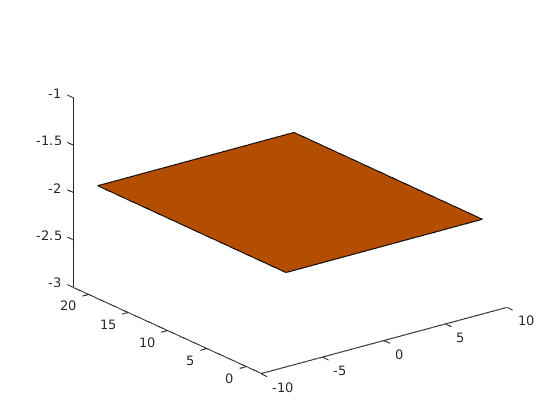

clc
clear

X_table = [8 -8 -8 8];
Y_table = [-2 -2 22 22];
Z_table = [-2 -2 -2 -2];

X=[1,0 0];
Y=[0,1,0];
Z=[0,0,1];

h2=fill3(X_table,Y_table,Z_table,[0.7 0.3 0]);

2.- A 3D model of a human body on the operating table. Use the Workspace given, or other you might find.

*Tambien estan los ficudals pero no se plotean despues de trasladarlos*

%Options
skin1 = 'r';
skin2 = [0.9290 0.6940 0.1250];
skull_color_2=[0 0 0.7];
skull_color_1=[1 1 1];
skul_height=3;

N=112;
height_img= round(skul_height/N,2);

%Dicom slices. Usamos la 100 y no la 19 porque sino queda muy abajo
z_Ficudal1=48;
z_Ficudal2=81;
z_Ficudal3=100;

[x,y,z] = sphere;
[x2,y2,z2] = sphere;
[x3,y3,z3] = sphere;

%Load
[V2,F2,UV2,TF2,N2,NF2] = readOBJ('Skull.obj');
[V,F,UV,TF,N,NF] = readOBJ('Human_body.obj');

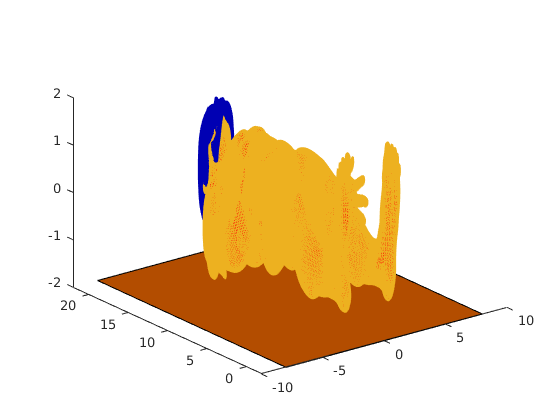

Ficudal1=[0 1.5 z_Ficudal1*height_img];
Ficudal2=[0.3 1.5 z_Ficudal2*height_img];
Ficudal3=[0.6 1.5 z_Ficudal3*height_img];
V2=V2*0.1;

%Rotate
alpha=pi/2;
R=rotx(alpha);
V2=V2*R;

%Ficudals

Ficudal1=Ficudal1*R;
Ficudal2=Ficudal2*R;
Ficudal3=Ficudal3*R;

%Translate
T= transl(0,6,0);

t1 = [Ficudal1 1]';
tt1 = T*t1;
Ficudal1 = tt1(1:3);

for i=1:size(V2,1)
    for j=1:size(V2,2)
            aux = [V2(i,:) 1]';
            P = T*aux;
            V2(i,:) = P(1:3);
    end
end


Ficudal1=Ficudal1';
Ficudal2=Ficudal2';
Ficudal3=Ficudal3';

%Display
figure
axis ([-10 10 -5 25 -2 20])

h2=fill3(X_table,Y_table,Z_table,[0.7 0.3 0]);
hold on
p = patch('faces',F,'vertices',V,'FaceColor',skin1,'EdgeColor',skin2);
hold on
p2 = patch('faces',F2,'vertices',V2,'FaceColor',skull_color_1,'EdgeColor',skull_color_2);
hold on
%surf(0.015*x+Ficudal1(1,1),0.015*y+Ficudal1(2,1),0.015*z+Ficudal1(3,1));

hold on
%surf(0.015*x2+Ficudal2(1,1),0.015*y2+Ficudal2(2,1),0.015*z2+Ficudal2(3,1));

hold on

%surf(0.015*x3+Ficudal3(1,1),0.015*y3+Ficudal3(2,1),0.015*z3+Ficudal3(3,1));



3.- A human skull model, embedded in the head of the human. Place the fiducials.

*Hemos probado de conseguir el bojeto 3D a traves de dicomreadVolume i de la Dicom Toolbox adjuntada pero no lo hemos logrado.*

% %Clean Workspace 
% clf
% 
% 
% figure
% axis ([-600 600 -200 200 -2000 20])
% hold on
% 
% %Load
% [V,F,UV,TF,N,NF] = readOBJ('Human_body.obj');
% skin1 = 'r';
% skin2 = [0.9290 0.6940 0.1250];
% 
% X_table = [8 -8 -8 8];
% Y_table = [-2 -2 22 22];
% Z_table = [-2 -2 -2 -2];
% 
% X=[1,0 0];
% Y=[0,1,0];
% Z=[0,0,1];
% 
% %Resize Human size
% V = V*70;
% 
% %Rotate
% alpha=-pi/2;
% R=rotx(alpha);
% V=V*R;
% 
% %Translate
% T= transl(0,0,-450);
% for i=1:size(V,1)
%     for j=1:size(V,2)
%             aux = [V(i,:) 1]';
%             P = T*aux;
%             V(i,:) = P(1:3);
%             V(i,:);
%     end
% end
% 
% %Display
% 
% h2=fill3(X_table,Y_table,Z_table,[0.7 0.3 0]);
% hold on
% p = patch('faces',F,'vertices',V,'FaceColor',skin1,'EdgeColor',skin2);
% 
% fiducals;
% 
% printSkull;



4.- Use the Dicom images to get the points of the outer perimeter of the tumor relative to some reference frame located in the human skull.

*Add your comemnts here.....be concise*

[x,y,z] = sphere;

Xo = 0;
Yo = 0;
Zo = 1;

Tumor=[Xo Yo Zo];


Tumor=Tumor*R;

%Translate

t1 = [Tumor 1]';
tt1 = T*t1;
Tumor = tt1(1:3);


Tumor = Tumor';

hold on

%surf(x+Tumor(1,1),y+Tumor(2,1),z+Tumor(3,1));

*First approach:**  Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

5.- Display all necessary Reference Frames

*Add your comemnts here.....be concise*

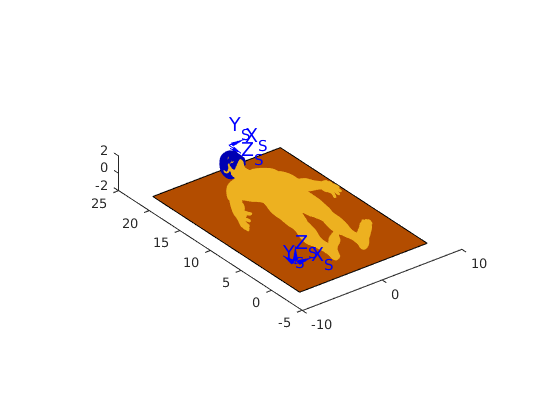

%Table
hold on
table=transl(-7,0,0)*eye(4);
trplot(table, 'frame','S','length',2,'text_opts', {'FontSize', 14},'arrow','color', 'b','thick',1);

%Skull

hold on
skull=transl(0,20,2)*trotx(alpha)*eye(4);
trplot(skull, 'frame','S','length',2,'text_opts', {'FontSize', 14},'arrow','color', 'b','thick',1);

6.- Place the 6R Robot manipulator nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560.

*Add your comemnts here.....be concise*

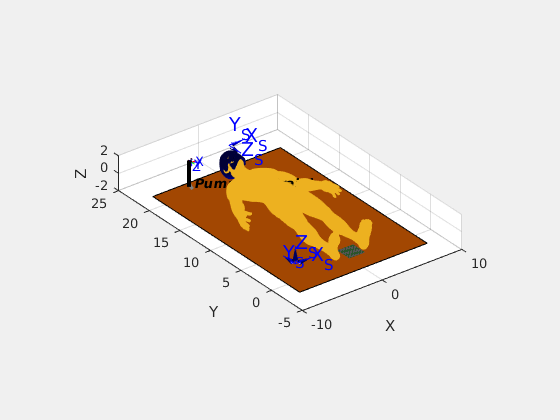

hold on
run mdl_puma560_Craigh

%p560Craigh.tool = SE3(0, 0, 0.2);

p560Craigh.base = SE3(-5, 20, 2);

%Plot
p560Craigh.plot(qz);

7.- Get the transformation that maps tumor points in Robot Frame.

*Add your comemnts here.....be concise*

%% put your code Here

8.- Print the tumor points in Robot Frame.

*Add your comemnts here.....be concise*

%% put your code Here

9.- Prepare a script that perform a biopsy. Zoom in the scene

*Add your comemnts here.....be concise*

%% put your code Here

10.- Prepare a script that perform trepanation.

*Add your comemnts here.....be concise*

%% put your code Here

11.- Prepare a script that perform tumor burning with the laser.

*Add your comemnts here.....be concise*

%% put your code Here

*Second approach:**  Assume that the ZX plane of the Robot is not aligned with plane of symetry of the human body and it is needed a orientation calibration.*

12.-Get the transformation that maps tumor points in Robot Frame. See teacher help: Triangle.mlx

*Add your comemnts here.....be concise*

%% put your code Here

13.- Print the tumor points in Robot Frame.

*Add your comemnts here.....be concise*

%% put your code Here

14.-Use the script that perform a biopsy. Zoom in the scene

*Add your comemnts here.....be concise*

%% put your code Here

15.- Use the  script that perform trepanation.

*Add your comemnts here.....be concise*

%% put your code Here

16.- Use the script that perform tumor burning with the laser.

*Add your comemnts here.....be concise*

%% put your code Here